RealSense Data Stream

align =   align with no properties.


Intel RealSense D435


colorIntrinsics = struct with fields:
     width: 1280
    height: 720
       ppx: 651.4588
       ppy: 359.4717
        fx: 644.1683
        fy: 644.1683
     model: 4
    coeffs: [0 0 0 0 0]


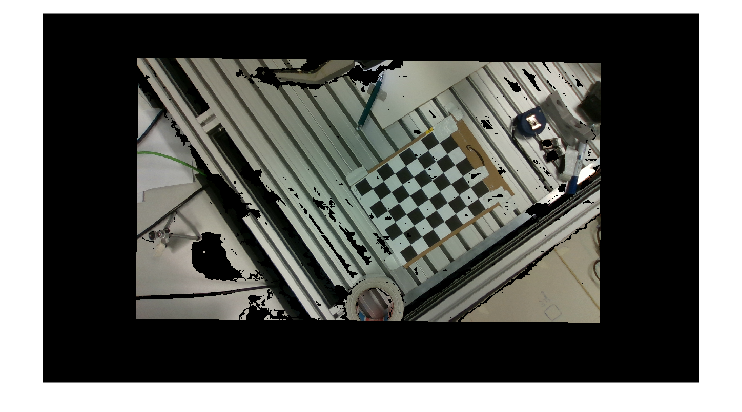

imagePointDepths =   732.0001
  733.0000
  730.0000
  740.0000


Unrecognized field name "FocalLength".

Error in stream_data_example>stream_data (line 109)
            fx = intrinsics.FocalLength(1);

stream_data(500)

function stream_data(frames)

    
    
    % set camera resolution to 1280 x 720 px for color and depth camera
    configuration = realsense.config();
    configuration.enable_stream(realsense.stream.color,-1, 1280, 720, realsense.format.rgb8, 0);
    configuration.enable_stream(realsense.stream.depth, 1280, 720, realsense.format.z16, 0);

    % align depth to color image
    align = realsense.align(realsense.stream.depth)

    % create Pipeline object to manage streaming
    pipe = realsense.pipeline();

    % start streaming on an arbitrary camera with default settings
    profile = pipe.start(configuration);

    % get streaming device's name to check connection
    dev = profile.get_device();
    name = dev.get_info(realsense.camera_info.name);
    disp(name);

    % load calibration data
    [imageSize, principalPoint, intrinsics] = getImageMetaData();
    
    % initialize the camera image
    initialImage = zeros(imageSize(1), imageSize(2) ,3,'uint8');
    Image = imshow(initialImage);


	frames = pipe.wait_for_frames();
	alignedFrames = align.process(frames);
	depth = alignedFrames.get_depth_frame();
    color = alignedFrames.get_color_frame();

	depthIntrinsics = depth.get_profile().as('video_stream_profile').get_intrinsics();
    colorIntrinsics = color.get_profile().as('video_stream_profile').get_intrinsics()

    intrinsics = colorIntrinsics;


    % discard the first couple frames to allow the camera time to settle
    for i = 1:5
        frames = pipe.wait_for_frames();
    end

    % main loop
    while true
        frames = pipe.wait_for_frames();
        alignedFrames = align.process(frames);
        color = alignedFrames.get_color_frame();
		depth = alignedFrames.get_depth_frame();
       

        % get actual data and convert into a format imshow can use
        % (Color data arrives as [R, G, B, R, G, B, ...] vector)
        colorData = color.get_data();
        colorImage = permute(reshape(colorData',[3,color.get_width(),color.get_height()]),[3 2 1]);

        % depthData = depth.get_data();
        % depthImage = permute(reshape(depthData',[3,depth.get_width(),depth.get_height()]),[3 2 1]);

        set(Image, 'CData', colorImage);
        hold on;
        
        % image points [x, y]
        [imagePoints, ~] = detectCheckerboardPoints(colorImage);

        

        % only proceed if the correct number of points is detected
        if size(imagePoints, 1) == 42 & or(~isnan(imagePoints(:, 1)), ~isnan(imagePoints(:, 2)))
        
            % get grid corners by calculating euclidean distances to grid center
            centerPoint = mean(imagePoints, 1);
            x = imagePoints(:, 1);
            y = imagePoints(:, 2);
            distances = sqrt((x-centerPoint(1)).^2 + (y-centerPoint(2)).^2);
            [~, indices] = maxk(distances, 4);

            imagePoints = imagePoints(indices, :);

            length = size(imagePoints, 1);

            imagePointDepths = zeros(length, 1);

            for i=1:length
                a = int32(imagePoints(i, 1));
                b = int32(imagePoints(i,2));
                imagePointDepths(i) = depth.get_distance(a, b) * 1000;
            end

            imagePointDepths

            % coordinates of the checkerboard corners in robot coordinates
            % first two points are measured manually
            robotPoints = [467.62 111.31 38.17;
                0 0 38.17;
                0 0 38.17;
                470.47 -28.69 40.48;];

            % the missing two points are calculated automatically
            robotPoints = deriveMissingPoints(robotPoints);


            % unpack intrinsics and cast into matlab array
            fx = intrinsics.FocalLength(1);
            fy = intrinsics.FocalLength(2);
            cx = intrinsics.PrincipalPoint(1);
            cy = intrinsics.PrincipalPoint(2);
            s = intrinsics.Skew;
            distortion = intrinsics.RadialDistortion;
            distortion(3:4) = intrinsics.TangentialDistortion;

            intrinsicMatrix = [fx s cx;
                0 fy cy;
                0 0 1];

            % prepare points and camera parameters for transfer to the python script
            pyRobotPoints = py.numpy.array(robotPoints);
            pyImagePoints = py.numpy.array(imagePoints(:, 1:2));
            pyIntrinsics = py.numpy.array(intrinsicMatrix);
            pyDistortion = py.numpy.array(distortion);

            % run the openCV solvePnP algorithm via python script
            pyExtrinsicMatrix = pyrunfile("./get_transformation.py", ["transformation_matrix"], ...
                wp=pyRobotPoints, ip=pyImagePoints, intrinsics=pyIntrinsics, distortion=pyDistortion);
            extrinsicMatrix = double(pyExtrinsicMatrix);


            rotationMatrix = double(extrinsicMatrix(1:3,1:3));
            invRotationMatrix = inv(rotationMatrix);
            translationVector = extrinsicMatrix(1:3, 4);

            augImagePoints = imagePoints;
            augImagePoints(:, 3) = imagePointDepths(:,1);

            % a = size(rotationMatrix)
            % b = size(inv(intrinsicMatrix))
            % c = size(translationVector)
            % 
            % d = size(augImagePoints)
            % d2 = size(augImagePoints(1,:)')

            length = size(augImagePoints, 1);

            testWorldPoints(length, 3) = 0;

            for i=1:length
                testWorldPoints(i, :) = inv(intrinsicMatrix) * augImagePoints(i,:)' - translationVector;
                testWorldPoints(i, :) = inv(rotationMatrix) * testWorldPoints(i, :)' ;
            end

            testWorldPoints




            % % the magic of maths
            % zConst = 0;
            % tempMatrix1 = invRotationMatrix * inv(intrinsicMatrix) * augImagePoints(1,:)';
            % tempMatrix2 = invRotationMatrix * translationVector;
            % s = (zConst + tempMatrix2(3,1)) / tempMatrix2(3,1);
            % 
            % worldPoint = invRotationMatrix * (s * inv(intrinsicMatrix) * augImagePoints' - translationVector);
     
            
            k = boundary(x, y);
    
            plot(x(k), y(k), "Color", "b", "LineWidth", 3);
    
            line([principalPoint(1), principalPoint(1)], [0, imageSize(1)], "Color", "k", "LineWidth", 3);
            line([0, imageSize(2)], [principalPoint(2), principalPoint(2)], "Color", "k", "LineWidth", 3);
    
            drawnow;
            hold off;
        end
    end % main loop
    
    % Stop streaming
    pipe.stop();
end

function [imageSize, principalPoint, intrinsics] = getImageMetaData()
% load camera parameters
load('.\cam_params_nina_medium_resolution.mat', 'cameraParams');

% display the variables in the loaded file
% whos;

imageSize = cameraParams.Intrinsics.ImageSize;
principalPoint = cameraParams.Intrinsics.PrincipalPoint;
intrinsics = cameraParams.Intrinsics;
end

function points = deriveMissingPoints(points)

edge_length = 30;

vectorA = points(4,1:2) - points(1, 1:2);
vectorA = vectorA / norm(vectorA);
vectorA(3) = 0;
vectorZ = [0 0 1];

vectorN = cross(-vectorA, vectorZ);

point2 = points(1, 1:2) + 6 * edge_length * vectorN(1:2);
point3 = points(4, 1:2) + 6 * edge_length * vectorN(1:2);

points(2, 1:2) = point2;
points(3, 1:2) = point3;
end



function detect_checkerboard(image, principalPoint)

% % Berechnen Sie das Zentrum des Bildes
% [imageHeight, imageWidth, ~] = size(image);
% imageCenterX = imageWidth / 2;
% imageCenterY = imageHeight / 2;

imshow(image);
hold on;
viscircles(principalPoint, 5);

% % detect the square corner points of the checkerboard
% [imagePoints, boardSize] = detectCheckerboardPoints(image);
% 
% % Define the world coordinates of checkerboard corners
% % This depends on the size of your checkerboard and the dimensions of the squares
% squareSize = 30; % square size in millimeters
% worldPoints = generateCheckerboardPoints(boardSize, squareSize);
% 
% % Estimate the pose of the checkerboard
% [rotationMatrix, translationVector] = extrinsics(imagePoints, worldPoints, cameraParams);
% 
% % Select a corner point to find its position (e.g., first corner)
% cornerIndex = 1;
% cornerWorldPoint = worldPoints(cornerIndex, :);
% 
% % Transform the corner point from world to camera coordinates
% % Reshape cornerWorldPoint to be a 3x1 column vector
% cornerWorldPoint = [cornerWorldPoint, 0]'; % Add a zero for the Z-coordinate
% cornerCameraPoint = (rotationMatrix * cornerWorldPoint) + translationVector';
% 
% % Display the result
% fprintf('Position of the corner in camera coordinates (in mm):\n X: %f (red)\n Y: %f (green)\n Z: %f (blue)\n', cornerCameraPoint);
% 
% % Visualize the detected corners on the image
% imshow(image);
% hold on;
% plot(imagePoints(:, 1), imagePoints(:, 2), 'ro'); % Plot all detected corners as red circles
% plot(imagePoints(cornerIndex, 1), imagePoints(cornerIndex, 2), 'go', 'MarkerSize', 10); % Highlight the selected corner with a green circle
% 
% % Draw the camera coordinate system axes
% % Axis length in pixels (you may need to adjust this based on your image)
% axisLength = 50;
% 
% % Draw the X-axis in red
% line([imagePoints(cornerIndex, 1), imagePoints(cornerIndex, 1) + axisLength], [imagePoints(cornerIndex, 2), imagePoints(cornerIndex, 2)], 'Color', 'r', 'LineWidth', 2);
% 
% % Draw the Y-axis in green
% line([imagePoints(cornerIndex, 1), imagePoints(cornerIndex, 1)], [imagePoints(cornerIndex, 2), imagePoints(cornerIndex, 2) - axisLength], 'Color', 'g', 'LineWidth', 2);
% 
% % Draw a crosshair at the center of the image
% % Draw a crosshair at the center of the image
% crosshairSize = 20; % size of the crosshair in pixels
% line([imageCenterX - crosshairSize, imageCenterX + crosshairSize], [imageCenterY, imageCenterY], 'Color', 'b', 'LineWidth', 2); % Horizontal line
% line([imageCenterX, imageCenterX], [imageCenterY - crosshairSize, imageCenterY + crosshairSize], 'Color', 'b', 'LineWidth', 2); % Vertical line

hold off;
end
